# BFGS

% f: 2 scalars -> 1 scalar
% hessian: 2 scalars -> 2x2 matrix
% dfdx: 2 scalars -> 2x1 vector
% x_n+1 = x_n - inv(H(f))*dfdx(x_n)
% H(f) d = -dfdx(x_n) --> x_n+1 = x_n+d

function [xs,n,converged] = BFGS(x0,y0,f,hessian0,dfdx,sigma,rho,N,tol)
    converged = false;

    n = 1;

    xs = zeros(N+1,2);
    xs(1,:) = [x0 y0];

    % n = number of elements in array = index of last x in array
    % n-1 = number of completed iterations
    % n-1 = index of last computed x

    g0 = dfdx(x0,y0);
    if norm(g0)<tol
        error("at min point already");
    end
    g = g0;

    Hinv = hessian0;

    fx = f(x0,y0);

    while n-1<N
        d = -1*Hinv*g;

        if norm(g) < tol*(1+norm(g0))
            converged = true;
            break;
        end

        alpha = 1;
        newx = xs(n,:) + alpha*d';
        newf = f(newx(1),newx(2));
        dhda = g'*d;

        %while(newf>=fx+alpha*sigma*dhda)
        %    alpha = alpha*rho;
        %    newx = xs(n,:)+alpha*d';
        %    newf = f(newx(1),newx(2));
        %    fprintf("newf=%d (%d,%d)\n",newf,newx(1),newx(2));
        %end
        

        n = n+1;
        xs(n,:) = newx;
        
        newg = dfdx(xs(n,1),xs(n,2));
        deltag = newg - g; %2x1 vector
        deltax = xs(n,:)-xs(n-1,:); %1x2 vector 

        %fprintf("deltax: %d %d\n", deltax(1),deltax(2));
        %fprintf("deltag: %d %d\n\n", deltag(1),deltag(2));

        s = deltax'; % Convert 1x2 to 2x1
        y = deltag;  % Already 2x1
        
        rho_bfgs = 1 / (y' * s);
        
        if (y' * s) > 1e-10 % Curvature condition
            I = eye(2);
            Hinv = (I - rho_bfgs * s * y') * Hinv * (I - rho_bfgs * y * s') + (rho_bfgs * s * s');
        else
            Hinv = eye(2); 
        end

        

        g = newg;
        fx = newf;
        fprintf("%d %d\n",xs(n,1),xs(n,2));
    end

    xs = xs(1:n,:);

    
end

## plot

function plot_function(ax,f,xmin,xmax,ymin,ymax)
    density = 100;
    xrange = xmax-xmin;
    yrange = ymax-ymin;

    [X,Y] = meshgrid(linspace(xmin,xmax,xrange*density),linspace(ymin,ymax,yrange*density));
    Z = f(X,Y);

    surf(ax,X,Y,Z,'EdgeColor','none');
    shading flat;
end

function plot_iteration(ax,f,xs)
    plot(ax,xs(1,1),xs(1,2),'.r','MarkerSize',9);
    
    n = length(xs);
    for i=2:n
        plot3(ax,[xs(i-1,1) xs(i,1)],[xs(i-1,2) xs(i,2)],[f(xs(i-1,1),xs(i-1,2)) f(xs(i,1),xs(i,2))],'-k','LineWidth',1);
        if i==n
            plot3(ax,xs(i,1),xs(i,2),f(xs(i,1),xs(i,2)),'.g','MarkerSize',9);
        else
            plot3(ax,xs(i,1),xs(i,2),f(xs(i,1),xs(i,2)),'.k','MarkerSize',9);
        end
    end
end

function plot_contours(ax,f,xmin,xmax,ymin,ymax)
    density = 10;
    xrange = xmax-xmin;
    yrange = ymax-ymin;

    [X,Y] = meshgrid(linspace(xmin,xmax,xrange*density),linspace(ymin,ymax,yrange*density));
    Z = f(X,Y);

    contourf(ax,X,Y,Z);
    colorbar(ax);
end

function plot_contour_descent(ax,xs)
    n = length(xs);
    plot(ax,xs(1,1),xs(1,2),'.r','MarkerSize',9);
    for i=2:n
        plot(ax,[xs(i-1,1) xs(i,1)],[xs(i-1,2) xs(i,2)],'-k','LineWidth',1);
        if(i==n)
            plot(ax,xs(i,1),xs(i,2),'.g','MarkerSize',9);
        else
            plot(ax,xs(i,1),xs(i,2),'.k','MarkerSize',9);
        end
    end
end

function plot_all(ax1,ax2,x0,y0,f,hessian0,dfdx,sigma,rho,N,tol,xmin0,xmax0,ymin0,ymax0)
    ratio = 0.6;

    [xs,n,converged] = BFGS(x0,y0,f,hessian0,dfdx,sigma,rho,N,tol);

    if n==1
        error("min already\n");
    end

    x = xs(:,1);
    y = xs(:,2);
    xmin = min(xmin0,min(x)-ratio*abs(min(x)));
    xmax = max(xmax0,max(x)+ratio*abs(max(x)));
    ymin = min(ymin0,min(y)-ratio*abs(min(y)));
    ymax = max(ymax0,max(y)+ratio*abs(max(y)));

    plot_function(ax1,f,xmin,xmax,ymin,ymax);
    plot_iteration(ax1,f,xs);

    plot_contours(ax2,f,xmin,xmax,ymin,ymax);
    plot_contour_descent(ax2,xs);

    if converged
        fprintf("Converged in %d steps\n",n);
    else
        fprintf("Not converged\n");
    end

    fprintf("(x,y) = (%d, %d)\n",x(end),y(end));
end

## variables

function a = f(x,y)
    a = x.^2+y.^2+exp(2.*x+y);
end

function d = dfdx(x,y)
    d = zeros(2,1);
    d(1) = 2.*x+2.*exp(2.*x+y);
    d(2) = 2.*y+exp(2.*x+y);
end

hessian0 = [1 0; 0 1];
sigma = 0.1;
rho = 0.5;

N = 5;
tol = 2e-7;

## driver

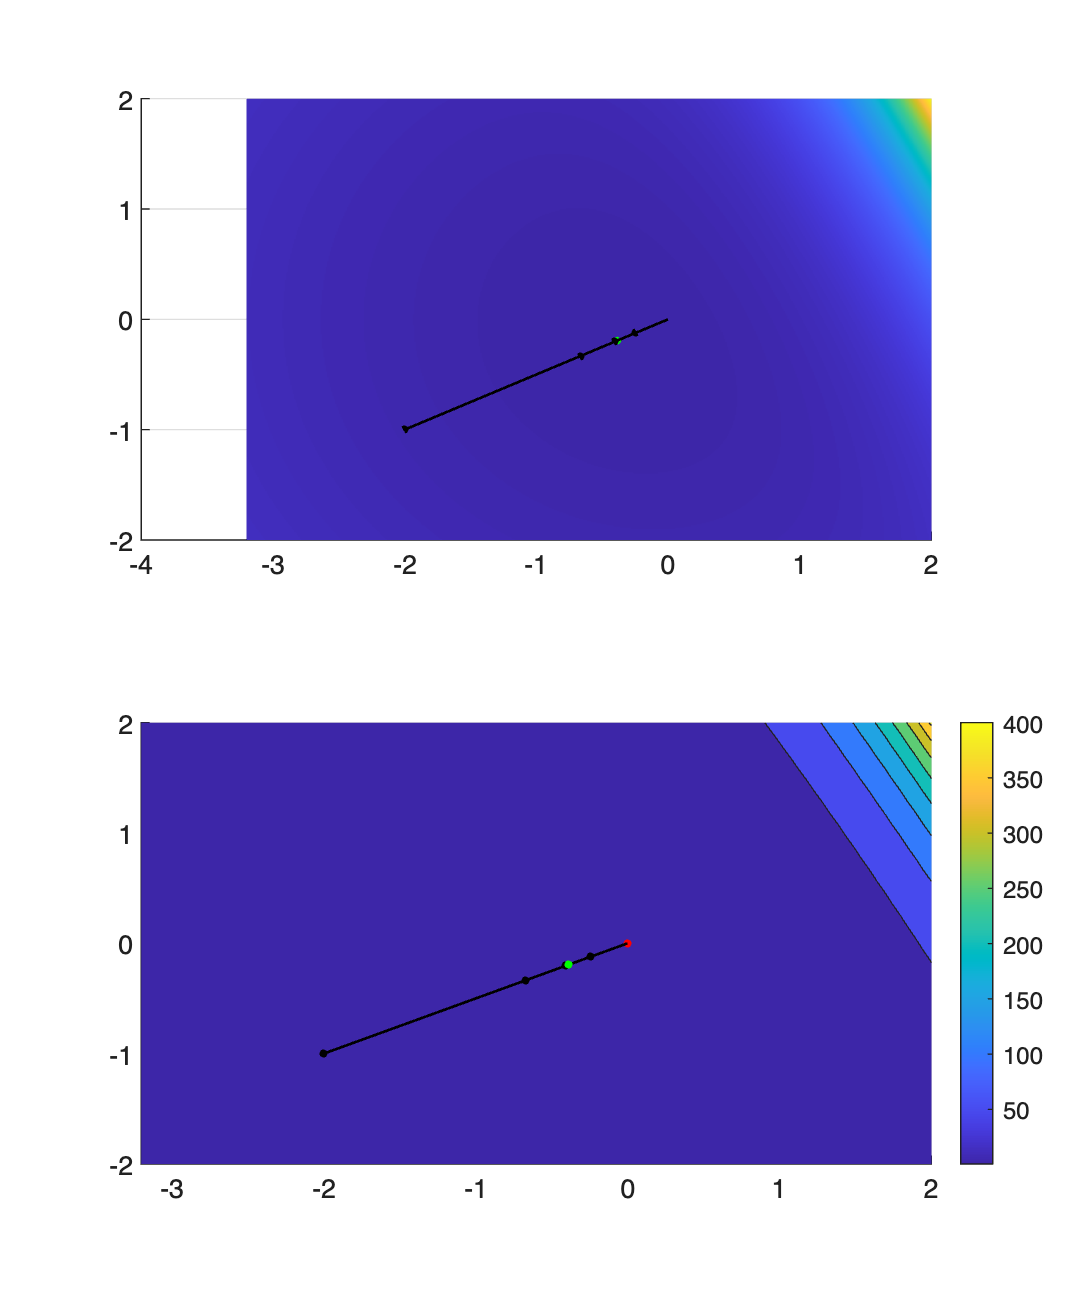

-2 -1
-6.681674e-01 -3.340837e-01
-2.457171e-01 -1.228585e-01
-4.066243e-01 -2.033122e-01
-3.854344e-01 -1.927172e-01
Not converged
(x,y) = (-3.854344e-01, -1.927172e-01)


h = figure;
h.Position(4) = h.Position(4)*2;

tiledlayout;
nexttile;
ax1 = gca;
nexttile;
ax2 = gca;

hold(ax1,'on');
grid(ax1,'on');
hold(ax2,'on');
grid(ax2,'on');

xmin0 = -2;
xmax0 = 2;
ymin0 = -2;
ymax0 = 2;

x0 = 0;
y0 = 0;
plot_all(ax1,ax2,x0,y0,@f,hessian0,@dfdx,sigma,rho,N,tol,xmin0,xmax0,ymin0,ymax0);